# Showing the "event triggered average" vs alpha function transient, per mouse

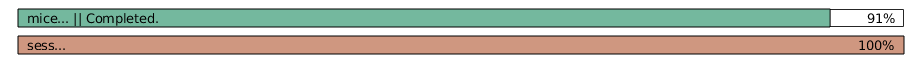

sm = SessManager;

mouse_names = sm.usable_mice;

progressbar('mice...', 'sess...');

for m_i = 1:numel(mouse_names)
    mouse_name = mouse_names{m_i};
    
    using_indices = strcmp(sm.meta.Mouse, mouse_name(6:end)) & ...
        sm.meta.Usable;
    m_vals = cellfun(@(x) ['Mouse' x], sm.meta.Mouse(using_indices), 'UniformOutput', false);
    s_vals = sm.meta.Session(using_indices);
    
    traces_sum = 0;
    traces_sum_sq = 0;
    counter = 0;
    for s_i = 1:numel(s_vals)
        pth = sm.cons_usable(sm.lookup_usable(m_vals{s_i}, s_vals{s_i}), true);
        pth = pth{1};
        ET = load(pth);
        tr = ET.tracesEvents.rawTraces;
        ev = ET.tracesEvents.HD_spikes;
        
        [n_frames, n_cells] = size(tr);
        for j = 1:n_cells
            my_tr = tr(:,j);
            my_ev = ev(:,j);

            onsets = find(my_ev);
            for k = 1:numel(onsets)
                my_onset = onsets(k);
                pre_frames = 20;
                post_frames = 80;

                my_range = my_onset - pre_frames : my_onset + post_frames;
                my_range = min(n_frames,max(1, my_range));

                
                counter = counter + 1;
                trace_segment = my_tr(my_range);
                traces_sum = traces_sum + trace_segment;
                traces_sum_sq = traces_sum_sq + trace_segment.^2;
            end
        end
        progressbar([], s_i/numel(s_vals));
    end
    traces_mean = traces_sum ./ counter;
    traces_mean_sq = traces_sum_sq ./ counter;
    
    traces_var = traces_mean_sq - traces_mean.^2;
    traces_std = sqrt(traces_var);
    traces_sem = traces_std ./ sqrt(counter);
    
    sta{m_i} = traces_mean;
    sta_sem{m_i} = traces_sem;
    progressbar(m_i / numel(mouse_names));
end

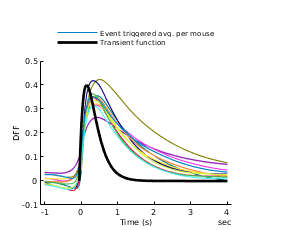

figure;
for m_i = 1:numel(mouse_names)
    fr = seconds((-pre_frames:post_frames)/20);
    ha = shadedErrorBar(fr, sta{m_i}, sta_sem{m_i}, 'lineProps', {'Color', DecodeTensor.mcolor(mouse_names(m_i), false)});
    hold on;
end

gamma = @(t) t.*exp(1-t);

t_vals = seconds(-1/20:0.01:4);
hg = plot(t_vals, 0.4*gamma((1/20+seconds(t_vals))*5), 'k', 'LineWidth', 2);
xlabel 'Time (s)'
ylabel 'DFF'
legend([ha.mainLine hg], 'Event triggered avg. per mouse', 'Transient function');
legend boxoff
legend location northoutside
figure_format([4 3]/2);
Utils.printto('events_figs/sta', 'sta.pdf');

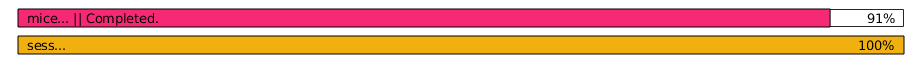

sm = SessManager;

mouse_names = sm.usable_mice;

progressbar('mice...', 'sess...');

for m_i = 1:numel(mouse_names)
    mouse_name = mouse_names{m_i};
    
    using_indices = strcmp(sm.meta.Mouse, mouse_name(6:end)) & ...
        sm.meta.Usable;
    m_vals = cellfun(@(x) ['Mouse' x], sm.meta.Mouse(using_indices), 'UniformOutput', false);
    s_vals = sm.meta.Session(using_indices);
    
    traces_sum = 0;
    traces_sum_sq = 0;
    counter = 0;
    for s_i = 1:numel(s_vals)
        pth = sm.cons_usable(sm.lookup_usable(m_vals{s_i}, s_vals{s_i}), true);
        pth = pth{1};
        ET = load(pth);
        tr = ET.tracesEvents.events_transients;
        ev = ET.tracesEvents.HD_spikes;
        
        [n_frames, n_cells] = size(tr);
        for j = 1:n_cells
            my_tr = tr(:,j);
            my_ev = ev(:,j);

            onsets = find(my_ev);
            for k = 1:numel(onsets)
                my_onset = onsets(k);
                pre_frames = 20;
                post_frames = 80;

                my_range = my_onset - pre_frames : my_onset + post_frames;
                my_range = min(n_frames,max(1, my_range));

                
                counter = counter + 1;
                trace_segment = my_tr(my_range);
                traces_sum = traces_sum + trace_segment;
                traces_sum_sq = traces_sum_sq + trace_segment.^2;
            end
        end
        progressbar([], s_i/numel(s_vals));
    end
    traces_mean = traces_sum ./ counter;
    traces_mean_sq = traces_sum_sq ./ counter;
    
    traces_var = traces_mean_sq - traces_mean.^2;
    traces_std = sqrt(traces_var);
    traces_sem = traces_std ./ sqrt(counter);
    
    sta{m_i} = traces_mean;
    sta_sem{m_i} = traces_sem;
    progressbar(m_i / numel(mouse_names));
end

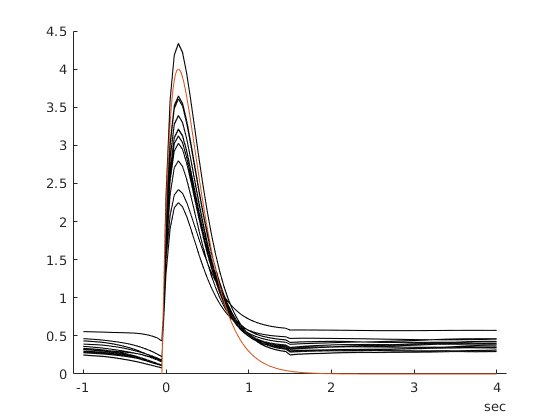

figure;
for m_i = 1:numel(mouse_names)
    fr = seconds((-pre_frames:post_frames)/20);
    serrorbar(fr, sta{m_i}, sta_sem{m_i});
    hold on;
end

gamma = @(t) t.*exp(1-t);

t_vals = seconds(-1/20:0.01:4);
plot(t_vals, 4*gamma((1/20+seconds(t_vals))*5));

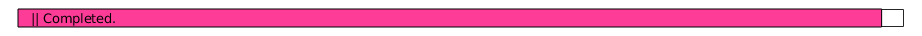

%traces_sum = 0;
%traces_sum_sq = 0;
%counter = 0;
gamma = @(t) t.*exp(1-t);
T = 1.5;
Fs = 20;
gamma_sample_times = linspace(0,7.5,T * Fs + 1);
gamma_sample_times = gamma_sample_times(2:end);
gamma_values = gamma(gamma_sample_times);

pth = sm.cons_usable(74, true);
pth = pth{1};
ET = load(pth);
tr = ET.tracesEvents.rawTraces;
ev = ET.tracesEvents.HD_spikes;
[n_frames, n_cells] = size(tr);

counter_one = 0;
all_tr_one = cell(1,n_cells);
%all_ev_one = cell(1,n_cells);

for j = 1:n_cells
    my_tr = tr(:,j);
    my_ev = ev(:,j);

    %ev_full = zeros(numel(gamma_values) + numel(my_tr) - 1, 1);
    %ev_full(1:numel(my_ev)) = my_ev;
    %my_ev_deconv = deconv(ev_full, gamma_values.');
    
    %onsets = my_ev ~= 0;%my_ev_deconv ~= 0;
    %onsets = [false ; diff(onsets) == 1];
    onsets = find(my_ev);
    for k = 1:numel(onsets)
        my_onset = onsets(k);
        pre_frames = 20;
        post_frames = 80;

        my_range = my_onset - pre_frames : my_onset + post_frames;
        my_range = min(n_frames,max(1, my_range));

        counter_one = counter_one + 1;
        all_tr_one{j}{k} = my_tr(my_range).';
        %all_ev_one{j}{k} = tr(my_range);
        %counter = counter + 1;
        %trace_segment = tr(my_range);
        %traces_sum = traces_sum + trace_segment;
        %traces_sum_sq = traces_sum_sq + trace_segment.^2;
    end
    progressbar(j/n_cells);
end

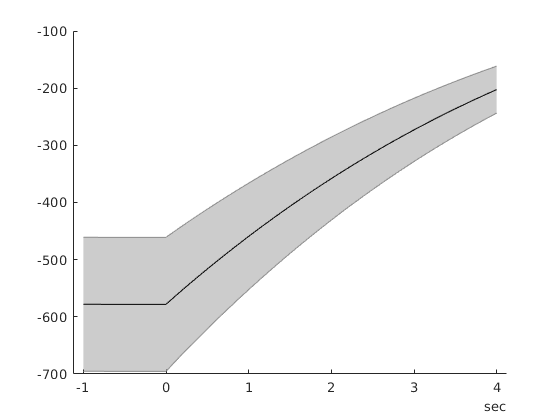


%traces_mean = traces_sum ./ counter;
%traces_mean_sq = traces_sum_sq ./ counter;

%traces_var = traces_mean_sq - traces_mean.^2;
%traces_std = sqrt(traces_var);
%traces_sem = traces_std ./ sqrt(counter);

all_tr_one = cell2mat([all_tr_one{:}].');
mean_tr_one = mean(all_tr_one, 1);
std_tr_one = std(all_tr_one, 0, 1);
sem_tr_one = std_tr_one ./ sqrt(size(all_tr_one,1));

figure;
fr = seconds((-pre_frames:post_frames)/20);
serrorbar(fr, mean_tr_one, sem_tr_one);

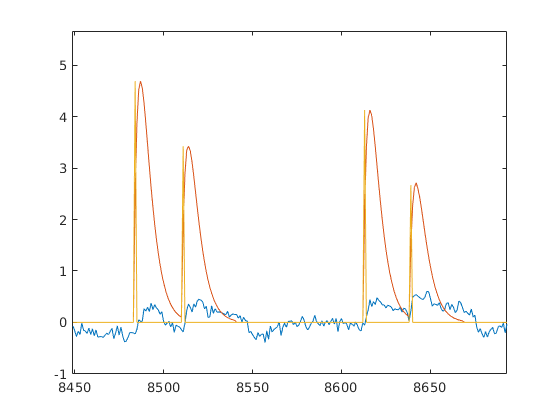

figure;
plot(my_tr);
hold on;
plot(my_ev);
gamma = @(t) t.*exp(1-t);
T = 1.5;
Fs = 20;
gamma_sample_times = linspace(0,7.5,T * Fs + 1);
gamma_sample_times = gamma_sample_times(2:end);
gamma_values = gamma(gamma_sample_times);

ev_full = zeros(numel(gamma_values) + numel(my_tr) - 1, 1);
ev_full(1:numel(my_ev)) = my_ev;
[my_ev_deconv, re] = deconv(my_ev, gamma_values);
plot(my_ev_deconv);

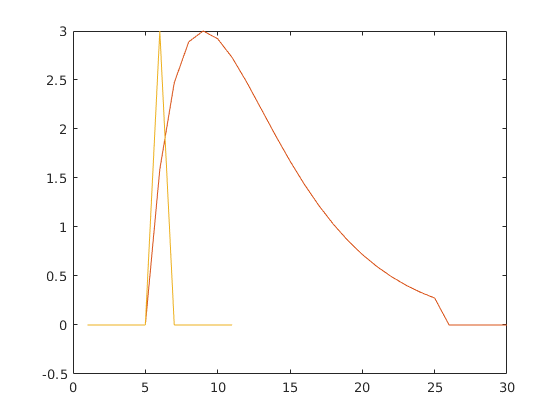

x = [0 0 0 0 0 3 0 0 0 0 0];
xg = conv(x, gamma_values);
[xd, re] = deconv(xg, gamma_values);

figure;
plot(x);
hold on;
plot(xg);
plot(xd);